format long
K=16;
N=64;
data=load("reliability_sequence.mat");
req=data.reliability_full(data.reliability_full<=N);
g=[1 0;1 1];
n=log2(N);
Gmat=1;
for i=1:n
    Gmat=kron(g,Gmat);
end
EbNodB = linspace(0,7,10);
Rate = (K*1.0)/N;
EbNo = 10.^(EbNodB/10);
EsNo=Rate.*EbNo;
sigma = sqrt(1.0./(2*EsNo));
Q1=req(req<=N);
F = Q1(1:N-K);
BLER=zeros(1,length(EbNodB));
tic;
Nblocks = 1000;
for i=1:length(sigma)
    x=0;
    for blk = 1:Nblocks
        msg = rand(1,K)<=0.5;
        u = zeros(1,N);
        u(Q1(N-K+1:end)) = msg;
        cword = mod(u*Gmat,2);
        s = 1-2*cword;
        r=s+sigma(i)*randn(1,N);
        rq=round((31*r)/3);
        L=zeros(n+1,N);
        ucap=zeros(n+1,N);
        ns=zeros(1,2*N-1);
        f = @(a,b) (1-2*(a<0)).*(1-2*(b<0)).*min(abs(a),abs(b));
        g = @(a,b,c) b+(1-2*c).*a;
        L(1,:)=rq;
        node=0; 
        depth=0;
        done=0;
        while(done==0)
            if(depth==n)
                if any(F==(node+1))
                    ucap(n+1,node+1)=0;
                else
                    if L(n+1,node+1)>=0
                        ucap(n+1,node+1)=0;
                    else
                        ucap(n+1,node+1)=1;
                    end
                end
                if node==(N-1)
                    done=1;
                else
                    node=floor(node/2); 
                    depth=depth-1;
                end
            else
                npos=(2^depth-1)+node+1;
                if(ns(npos)==0)
                    temp=2^(n-depth);
                    Ln = L(depth+1,temp*node+1:temp*(node+1));
                    temp=temp/2;
                    a=Ln(1:temp);
                    b=Ln(temp+1:end);
                    node=node*2; 
                    depth=depth+1;
                    L(depth+1,temp*node+1:temp*(node+1))=f(a,b);
                    ns(npos) = 1;
                else
                    if ns(npos)==1
                        temp=2^(n-depth);
                        Ln=L(depth+1,temp*node+1:temp*(node+1));
                        a=Ln(1:temp/2); 
                        b=Ln(temp/2+1:end);
                        lnode=2*node; 
                        ldepth=depth+1;
                        ltemp=temp/2;
                        ucapn=ucap(ldepth+1,ltemp*lnode+1:ltemp*(lnode+1));
                        node=node*2+1; 
                        depth=depth+1;
                        temp=temp/2;
                        L(depth+1,temp*node+1:temp*(node+1))=g(a,b,ucapn);
                        ns(npos)=2;
                    else
                        temp=2^(n-depth);
                        lnode=2*node; 
                        rnode=2*node+1; 
                        cdepth=depth+1;
                        ctemp=temp/2;
                        ucapl=ucap(cdepth+1,ctemp*lnode+1:ctemp*(lnode+1));
                        ucapr=ucap(cdepth+1,ctemp*rnode+1:ctemp*(rnode+1));
                        ucap(depth+1,temp*node+1:temp*(node+1))=[mod(ucapl+ucapr,2) ucapr];
                        node=floor(node/2); 
                        depth=depth-1;
                    end
                end
            end
        end
        msg_cap = ucap(n+1,Q1(N-K+1:end));
        bite=sum(msg~=msg_cap);
        if(bite>0)
            x=(x+1);
        end
    end
    BLER(i)=(x*1.0)/(Nblocks*1.0);
end
toc;

Elapsed time is 5.002122 seconds.


figure;
semilogy(EbNodB(1,:),BLER(1,:));
disp(BLER);

   0.337000000000000   0.205000000000000   0.141000000000000   0.055000000000000   0.023000000000000   0.004000000000000   0.002000000000000                   0                   0                   0



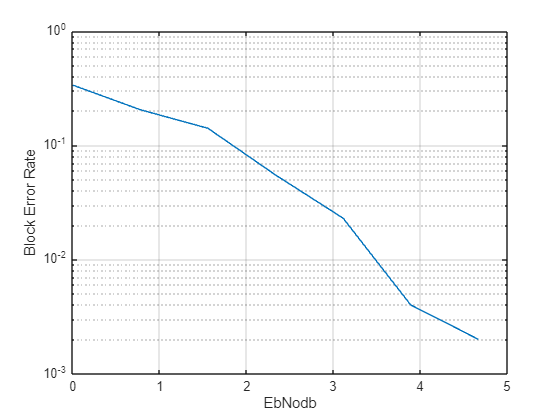

grid on;
BLER;
hold on;
xlabel('EbNodb');
ylabel('Block Error Rate');